## FINAL CODE

%function dePillisSoln 
patient = "mouse";

% scenario values
% "Fig6a", "Fig6b", "Fig6c", "Fig6d","Fig7a", "Fig7b","Fig8a", "Fig8b, Fig9a, Fig9b"
scenario = "Fig6a";


% Defining t range and intervals 
t0 = 0;
tf = 120;
trange =linspace(t0, tf, 2501);
vL_on = 0;% vL_on = 1 for immunotherapy dose ON in mice and vL_on = 0 for dose OFF
vM_on = 0; % vM_on = 1 for chemotherapy dose ON and vM_on = 0 for chemotherapy dose OFF
vI_on = 0; % vI_on = 1 for immunotherapy dose ON in humans and vI_on = 0 for dose OFF

T0 = 1e6;
C0 = 1.1e7; 
L0 = 100; 
N0 = 5e4;
M0 = 0;
I0 = 0;

numerators0 = [T0; N0; L0; C0; M0; I0];
% Setting senario 
if strcmp(scenario,"Fig6b") || strcmp(scenario,"Fig6d") || strcmp(scenario,"Fig8a") || strcmp(scenario,"Fig8b") ||...
        strcmp(scenario,"Fig10a") || strcmp(scenario,"Fig12a") || strcmp(scenario,"Fig12b") || strcmp(scenario,"Fig12c") ||...
        strcmp(scenario,"Fig12a") || strcmp(scenario,"Fig13c")
    vM_on = 1;
end

if strcmp(scenario,"Fig6c") || strcmp(scenario,"Fig6d") || strcmp(scenario,"Fig9a") || strcmp(scenario,"Fig9b") || strcmp(scenario,"Fig10a") ||...
        strcmp(scenario,"Fig12a") || strcmp(scenario,"Fig12b") || strcmp(scenario,"Fig12c")
    vL_on = 1;
end

if strcmp(scenario,"Fig9a") ||strcmp(scenario,"Fig9b") || strcmp(scenario,"Fig10a") || strcmp(scenario,"Fig12a") ||...
        strcmp(scenario,"Fig12b") || strcmp(scenario,"Fig12c")
    vI_on = 1;
end

% % Setting senario 
% if scenario == "Fig6b" || scenario == "Fig6d" || scenario == "Fig8a" || scenario == "Fig8b" || scenario == "Fig10a" || scenario == "Fig12a" || scenario == "Fig12b" || scenario == "Fig12c" || scenario == "Fig13a" || scenario == "Fig13c"
%     vM_on = 1;
% end
% 
% if scenario == "Fig6c" || scenario == "Fig6d" || scenario == "Fig9a" || scenario == "Fig9b" || scenario == "Fig10a" || scenario == "Fig12a" || scenario == "Fig12b" || scenario == "Fig12c"
%     vL_on = 1;
% end
% 
% if scenario == "Fig9a" || scenario == "Fig9b" || scenario == "Fig10a" || scenario == "Fig12a" || scenario == "Fig12b" || scenario == "Fig12c"
%     vI_on = 1;
% end

params = [vL_on; vM_on; vI_on; patient; scenario];
%params = [vL_on, vM_on, vI_on, patient, scenario]

## Call ODE45

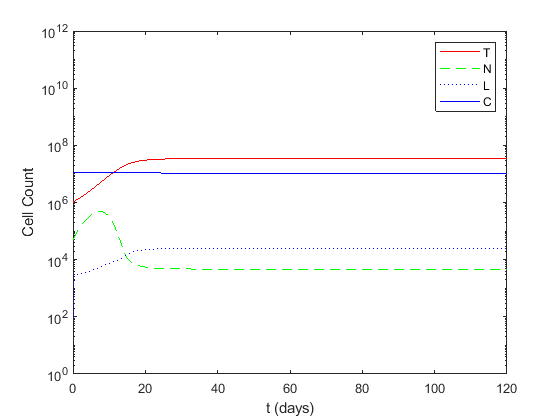


%% Call Ode45
% Call odeint to solve ODEs
[t,y]=ode45(@(t,numerators)solveODEs(t,numerators,params),trange,numerators0);

%soln=ode45(@solveODEs,trange,numerators0,params);
%Output vectors of numerators for each value of the denominator in the Vrange
% T = soln(:,1);
% N = soln(:,2);
% L = soln(:,3);
% C = soln(:,4);
% M = soln(:,5);
% I = soln(:,6);
 T = y(:,1);
 N = y(:,2);
 L = y(:,3);
 C = y(:,4);
 M = y(:,5);
 I = y(:,6);
% T = soln(1);
% N = soln(2);
% L = soln(3);
% C = soln(4);
% M = soln(5);
% I = soln(6);

if scenario == "Fig12c"
    figure(1)
    semilogy(trange,T,'r-')
    hold on
    semilogy(trange,N,'g--')
    semilogy(trange,L,'b:')
    semilogy(trange,C,'b-')
    xlim([0,2000])
    ylim([10^0, 10^12])
    legend('T','N','L','C')
    xlabel('t (days)')
    ylabel('Cell Count')
    
end
if scenario == "Fig13a" || scenario == "Fig13b" || scenario == "Fig13c" || scenario == "Fig14a" || scenario == "Fig14b"
    figure(1)
    semilogy(trange,T,'r-')
    hold on
    semilogy(trange,N,'g--')
    semilogy(trange,L,'b:')
    xlim([0,50])
    ylim([10^0, 10^12])
    legend('T','N','L')
    xlabel('t (days)')
    ylabel('Cell Count')
end

figure(2)
semilogy(trange,T,'r-')
hold on
semilogy(trange,N,'g--')
semilogy(trange,L,'b:')
semilogy(trange,C,'b-')
xlim([0,tf])
ylim([10^0, 10^12])
legend('T','N','L','C')
xlabel('t (days)')
ylabel('Cell Count')

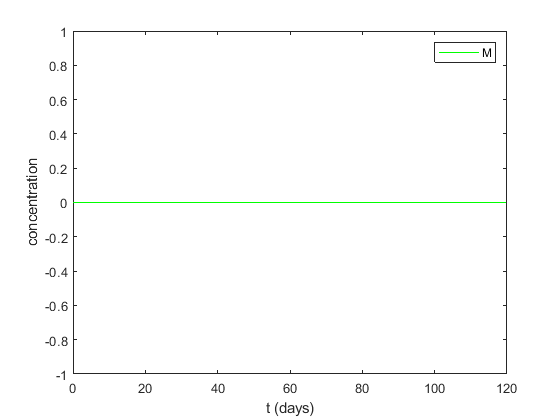




figure(3)
plot(trange,M,'g-')
legend('M')
xlabel('t (days)')
ylabel('concentration')

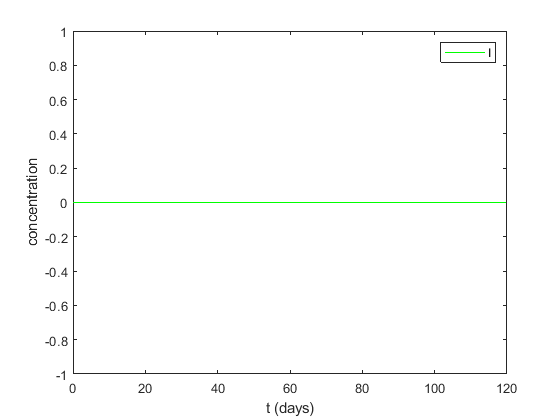


figure(4)
plot(trange,I,'g-')
legend('I')
xlabel('t (days)')
ylabel('concentration')

## Defining ODEs

function dsolveODEs=solveODEs(t,numerators,params) %% params
    
        T = numerators(1); % Tumor Cell Population
        N = numerators(2); % Total Nk Cell Population
        L = numerators(3); % Total CD8+T Cell Population
        C = numerators(4); % Number of Lympgocytes
        M = numerators(5); % Chemotherapy Blood Concentration 
        I = numerators(6); % Immunotherapy Blood Concentration
        vL_on = str2double(params(1)); % TIL drung intervention
        vM_on = str2double(params(2)); % Chemoherapy drug intervention
        vI_on = str2double(params(3)); % Immunotherapy drug intervention 
        patient = params(4);
        scenario = params(5);
        vL = 0;
        vM = 0;
        vI = 0;
        
        
        
       %%%% Params
       
       if vM_on == 1  
           
        if strcmp(patient,"mouse")        
            dose_frequency = 14;
            if mod(t, dose_frequency)<1
                vM = 1;
            end
        
       elseif strcmp(patient,"9")
            dose_frequency = 5;
            if t < 45
                if mod(t, dose_frequency)<1 
                    vM = 5;
                end
            end
       elseif strcmp(patient,"10") && strcmp(scenario,"Fig8a")
            dose_frequency = 5;
            if t < 45
                if mod(t, dose_frequency)<1
                    vM = 5;
                end
            end
       elseif strcmp(patient,"10") && strcmp(scenario,"Fig8b")
            dose_frequency = 10; % every 10 days
            if t < 90 % dose until 90 days
                if mod(t, dose_frequency) <1 %each dose lasts one day
                    vM = 5; % strength
                end
            end
       elseif strcmp(patient,"10") && strcmp(scenario,"Fig12a") || strcmp(scenario,"Fig12b") || strcmp(scenario,"Fig12c")
            dose_frequency = 10; % every 10 days
            if t < 90 % dose until 90 days
                if mod(t, dose_frequency)<2 %each dose lasts one day
                    vM = 5; % strength
                end
            end
       elseif strcmp(patient,"9") && strcmp(scenario,"Fig10a")
            dose_frequency = 10; % every 10 days
            if t < 90 % dose until 90 days
                if mod(t, dose_frequency)<1 %each dose lasts one day
                    vM = 5; % strength
                end
            end
       elseif strcmp(patient,"10") && strcmp(scenario,"Fig13a") || strcmp(scenario,"Fig13c")
            dose_frequency = 10; % every 10 days
            if mod(t, dose_frequency) <3 % each dose lasts one day
                vM = 2; % strength
            end
        end
       end
       
       
            %vM = 2 and administered for 3 consecutive days in a 10 day cycle
           %Fig 13b is just the vaccination treatment. In text they said to simulate the vaccination they raised the parameters. Does this mean nothing is on?
            
    
            
            
            
            
            
            
            
            
            
     if vL_on == 1
        if strcmp(patient,"9") && strcmp(scenario,"Fig9a") || strcmp(scenario,"Fig9b") 
            if t >= 7
                if t <= 8
                    vL = 1e9;
                end
            end
        elseif strcmp(patient,"mouse") && strcmp(scenario,"Fig6c") || strcmp(scenario,"Fig6d")
            dose_frequency = 1;
            if t >= 7
                if t <= 8
                    vL = 8e8;
                end
            end
        elseif strcmp(patient,"9") && strcmp(scenario,"Fig10a")
            if t >= 7
                if t <= 8
                    vL = 1e9;
                end
            end
        elseif strcmp(patient,"10") && strcmp(scenario,"Fig12a") || strcmp(scenario,"Fig12b") || scenario == "Fig12c"
            if t >= 7
                if t <= 8
                    vL = 1e9;
                end
            end
        end
     end
           

    
                    
                    
                    
                    
                    
                    
                    
                    
                    
                    
 if vI_on == 1 
        if strcmp(patient,"9") && strcmp(scenario,"Fig9a") || strcmp(scenario,"Fig9b")
            if t >= 8
                if t <= 11
                    dose_frequency= 0.5; % 6 times between 8 and 11 days, 3 days/6 times = every 0.5 days
                    if mod(t, dose_frequency)<0.01 % pulse
                        vI = 5e6; %strength
                    end
                end
            end
        elseif strcmp(patient,"9") && strcmp(scenario,"Fig10a")
            if t >= 8
                if t <= 11
                    dose_frequency= 0.5;
                    if mod(t, dose_frequency) <0.01 
                        vI = 5e5;
                    end
                end
            end
        elseif strcmp(patient,"10") && strcmp(scenario,"Fig12a")
            if t >= 8
                if t <= 11
                    dose_frequency= 0.5;
                    if mod(t, dose_frequency) <0.01 
                        vI = 5e6;
                    end
                end
            end
        elseif strcmp(patient,"10") && strcmp(scenario,"Fig12b") || strcmp(scenario,"Fig12c") % day 8-13 then 20-25, then 80-90 
            %unsure of how to add the multiple day intervals in one if-then statment
            %should I make more than one if-then statement?
            if t >= 8
                if t <= 13
                    dose_frequency= 0.833;
                    if mod(t, dose_frequency) <0.01
                        vI = 5e6;
                    end
                end
            end
        end
 end
                        
                        
                        
                        
                        
                        
                        
                        
                        
                        
                        
                        
                        
    if patient == "9"  % All parameters Patient 9
        a = 4.31e-1; % day^-1
        b = 1.02e-9; % cells^-1
        c = 6.41e-11; % cells^-1day^-1
        d = 2.34; % day^-1
        l = 2.09; % none
        s = 8.39e-2; % none
        e = 2.08e-7; % day^-1
        f = 4.12e-2; % day^-1
        g = 1.25e-2; % day^-1
        h = 2.02e7; % cell^2
        p = 3.42e-6; % cells^-1day^-1
        m = 2.04e-1; % day^-1
        j = 2.49e-2; % day^-1
        k = 3.66e7; % cell^2
        q = 1.42e-6; % cells^-1day^-1
        r1 = 1.1e-7 ;% cells^-1day^-1
        r2 = 6.5e-11 ;% cells^-1day^-1
        u = 3.00e-10 ;% cells^-2day^-1
        KT = 9.00e-1 ;% day^-1
        KNLC = 6.00e-1 ;% day^-1
        A = 7.5e8 ;% cellday^-1
        B = 1.20e-2 ;% day^-1
        V = 9.00e-1 ;% day^-1
        mu = 10;
        gI = 2e7;
        pI = 1.25e-1 ;%day^-1
    elseif patient == "mouse"
        a = 4.31e-1; % day^-1
        b = 2.17e-8 ;% cells^-1
        c = 7.13e-10 ;% cells^-1day^-1
        d = 8.17 ;% day^-1
        l = 6.57e-1 ;% none
        s = 6.18e-1 ;% none
        e = 1.29e-3 ;% day^-1
        f = 4.12e-2 ;% day^-1
        g = 4.98e-1 ;% day^-1
        h = 2.02e7 ;% cell^2
        p = 1.0e-7 ;% cells^-1day^-1
        m = 2.0e-2 ;% day^-1
        j = 9.96e-1 ;% day^-1
        k = 3.03e5 ;% cell^2
        q = 3.42e-10 ;% cells^-1day^-1
        r1 = 1.1e-7 ;% cells^-1day^-1
        r2 = 3.0e-11 ;% cells^-1day^-1
        u = 1.80e-8 ;% cells^-2day^-1
        KT = 9.00e-1 ;% day^-1
        KNLC = 6.00e-1 ;% day^-1
        A = 1.21e5 ;% cellday^-1
        B = 1.20e-2 ;% day^-1
        V = 9.00e-1 ;% day^-1
        mu = 10;
        gI = 2e7;
        pI = 1.25e-1;
    elseif patient == "10" && scenario == "Fig11a" || scenario == "Fig11b" || scenario == "Fig12a" || scenario == "Fig12b" || scenario == "Fig12c" || scenario == "Fig13a" 
        a = 4.31e-1; % day^-1
        b = 1.02e-9 ;% cells^-1
        c = 6.41e-11 ;% cells^-1day^-1
        d = 1.88 ;% day^-1
        l = 1.81 ;% none
        s = 5.12e-1 ;% none
        e = 2.08e-7 ;% day^-1
        f = 4.12e-2 ;% day^-1
        g = 1.25e-2 ;% day^-1
        h = 2.02e7 ;% cell^2
        p = 3.59e-6 ;% cells^-1day^-1
        m = 9.12 ;% day^-1
        j = 2.49e-2 ;% day^-1
        k = 5.66e7 ;% cell^2
        q = 1.59e-6 ;% cells^-1day^-1
        r1 = 1.1e-7 ;% cells^-1day^-1
        r2 = 6.5e-11 ;% cells^-1day^-1
        u = 3.00e-10 ;% cells^-2day^-1
        KT = 9.00e-1 ;% day^-1
        KNLC = 6.00e-1 ;% day^-1
        A = 5e8 ;% cellday^-1
        B = 8e-3 ;% day^-1
        V = 9.00e-1 ;% day^-1
        mu = 10;
        gI = 2e7;
        pI = 1.25e-1 ;%day^-1
    elseif patient == "10" && scenario == "Fig13b" || scenario == "Fig13c"
        if t <= 14.5
            a = 4.31e-1 ;% day^-1
            b = 1.02e-9 ;% cells^-1
            c = 6.41e-11 ;% cells^-1day^-1
            d = 1.88 ;% day^-1
            l = 1.81 ;% none
            s = 5.12e-1 ;% none
            e = 2.08e-7 ;% day^-1
            f = 4.12e-2 ;% day^-1
            g = 1.25e-2 ;% day^-1
            h = 2.02e7 ;% cell^2
            p = 3.59e-6 ;% cells^-1day^-1
            m = 9.12 ;% day^-1
            j = 2.49e-2 ;% day^-1
            k = 5.66e7 ;% cell^2
            q = 1.59e-6 ;% cells^-1day^-1
            r1 = 1.1e-7 ;% cells^-1day^-1
            r2 = 6.5e-11 ;% cells^-1day^-1
            u = 3.00e-10 ;% cells^-2day^-1
            KT = 9.00e-1 ;% day^-1
            KNLC = 6.00e-1 ;% day^-1
            A = 5e8 ;% cellday^-1
            B = 8e-3 ;% day^-1
            V = 9.00e-1 ;% day^-1
            mu = 10;
            gI = 2e7;
            pI = 1.25e-1 ;%day^-1
        end
        if t > 14.5
            a = 4.31e-1 ;% day^-1
            b = 1.02e-9 ;% cells^-1
            c = 7.131e-9 ;% cells^-1day^-1
            d = 15 ;% day^-1
            l = 1.81 ;% none
            s = 0.0019 ;% none
            e = 2.08e-7 ;% day^-1
            f = 4.12e-2 ;% day^-1
            g = 0.5 ;% day^-1
            h = 2.02e7 ;% cell^2
            p = 3.59e-6 ;% cells^-1day^-1
            m = 9.12 ;% day^-1
            j = 1 ;% day^-1
            k = 5.66e7 ;% cell^2
            q = 1.59e-6 ;% cells^-1day^-1
            r1 = 1.1e-7 ;% cells^-1day^-1
            r2 = 6.5e-11 ;% cells^-1day^-1
            u = 3.00e-10 ;% cells^-2day^-1
            KT = 9.00e-1 ;% day^-1
            KNLC = 6.00e-1 ;% day^-1
            A = 5e8 ;% cellday^-1
            B = 8e-3 ;% day^-1
            V = 9.00e-1 ;% day^-1
            mu = 10;
            gI = 2e7;
            pI = 1.25e-1 ;%day^-1
        end
    elseif patient == "10" && scenario == "Fig14a"
        if t < 13
            a = 4.31e-1 ;% day^-1
            b = 1.02e-9 ;% cells^-1
            c = 6.41e-11 ;% cells^-1day^-1
            d = 1.88 ;% day^-1
            l = 1.81 ;% none
            s = 5.12e-1 ;% none
            e = 2.08e-7 ;% day^-1
            f = 4.12e-2 ;% day^-1
            g = 1.25e-2 ;% day^-1
            h = 2.02e7 ;% cell^2
            p = 3.59e-6 ;% cells^-1day^-1
            m = 9.12 ;% day^-1
            j = 2.49e-2 ;% day^-1
            k = 5.66e7 ;% cell^2
            q = 1.59e-6 ;% cells^-1day^-1
            r1 = 1.1e-7 ;% cells^-1day^-1
            r2 = 6.5e-11 ;% cells^-1day^-1
            u = 3.00e-10 ;% cells^-2day^-1
            KT = 9.00e-1 ;% day^-1
            KNLC = 6.00e-1 ;% day^-1
            A = 5e8 ;% cellday^-1
            B = 8e-3 ;% day^-1
            V = 9.00e-1 ;% day^-1
            mu = 10;
            gI = 2e7;
            pI = 1.25e-1 ;%day^-1
        end
        if t >= 13
            a = 4.31e-1 ;% day^-1
            b = 1.02e-9 ;% cells^-1
            c = 7.131e-9 ;% cells^-1day^-1
            d = 15 ;% day^-1
            l = 1.81 ;% none
            s = 0.0019 ;% none
            e = 2.08e-7 ;% day^-1
            f = 4.12e-2 ;% day^-1
            g = 0.5 ;% day^-1
            h = 2.02e7 ;% cell^2
            p = 3.59e-6 ;% cells^-1day^-1
            m = 9.12 ;% day^-1
            j = 1 ;% day^-1
            k = 5.66e7 ;% cell^2
            q = 1.59e-6 ;% cells^-1day^-1
            r1 = 1.1e-7 ;% cells^-1day^-1
            r2 = 6.5e-11 ;% cells^-1day^-1
            u = 3.00e-10 ;% cells^-2day^-1
            KT = 9.00e-1 ;% day^-1
            KNLC = 6.00e-1 ;% day^-1
            A = 5e8 ;% cellday^-1
            B = 8e-3 ;% day^-1
            V = 9.00e-1 ;% day^-1
            mu = 10;
            gI = 2e7;
            pI = 1.25e-1 ;%day^-1
        end
    elseif patient == "10" && scenario == "Fig14b"
        if t < 14
            a = 4.31e-1 ;% day^-1
            b = 1.02e-9 ;% cells^-1
            c = 6.41e-11 ;% cells^-1day^-1
            d = 1.88 ;% day^-1
            l = 1.81 ;% none
            s = 5.12e-1 ;% none
            e = 2.08e-7 ;% day^-1
            f = 4.12e-2 ;% day^-1
            g = 1.25e-2 ;% day^-1
            h = 2.02e7 ;% cell^2
            p = 3.59e-6 ;% cells^-1day^-1
            m = 9.12 ;% day^-1
            j = 2.49e-2 ;% day^-1
            k = 5.66e7 ;% cell^2
            q = 1.59e-6 ;% cells^-1day^-1
            r1 = 1.1e-7 ;% cells^-1day^-1
            r2 = 6.5e-11 ;% cells^-1day^-1
            u = 3.00e-10 ;% cells^-2day^-1
            KT = 9.00e-1 ;% day^-1
            KNLC = 6.00e-1 ;% day^-1
            A = 5e8 ;% cellday^-1
            B = 8e-3 ;% day^-1
            V = 9.00e-1 ;% day^-1
            mu = 10;
            gI = 2e7;
            pI = 1.25e-1 ;%day^-1
        end
        if t >= 14
            a = 4.31e-1 ;% day^-1
            b = 1.02e-9 ;% cells^-1
            c = 7.131e-9 ;% cells^-1day^-1
            d = 15 ;% day^-1
            l = 1.81 ;% none
            s = 0.0019 ;% none
            e = 2.08e-7 ;% day^-1
            f = 4.12e-2 ;% day^-1
            g = 0.5 ;% day^-1
            h = 2.02e7 ;% cell^2
            p = 3.59e-6 ;% cells^-1day^-1
            m = 9.12 ;% day^-1
            j = 1 ;% day^-1
            k = 5.66e7 ;% cell^2
            q = 1.59e-6 ;% cells^-1day^-1
            r1 = 1.1e-7 ;% cells^-1day^-1
            r2 = 6.5e-11 ;% cells^-1day^-1
            u = 3.00e-10 ;% cells^-2day^-1
            KT = 9.00e-1 ;% day^-1
            KNLC = 6.00e-1 ;% day^-1
            A = 5e8 ;% cellday^-1
            B = 8e-3 ;% day^-1
            V = 9.00e-1 ;% day^-1
            mu = 10;
            gI = 2e7;
            pI = 1.25e-1 ;%day^-1
        end
    end
        
        D = d*((L/T)^l)/(s+((L/T)^l));
            
        % Define the derivatives
        % Population or mass balances 
        if T > 1
            dTdt = a*T*(1-b*T)-c*N*T-D*T-KT*(1-exp(-M))*T;
        else
            dTdt = 0;
        end
        if N >1
            dNdt = e*C-f*N+g*((T^2)/(h+T^2))*N-p*N*T-KNLC*(1-exp(-M))*N;
        else
            dNdt = 0;
        end
        if L > 1                 
            dLdt = -m*L+j*(((D^2)*(T^2))/(k+((D^2)*(T^2))))*L-(q*L*T)+((r1*N)+(r2*C))*T-(u*N*(L^2))-KNLC*(1-exp(-M))*L+((pI*L*I)/(gI+I))+vL;
        else
            dLdt = 0;
        end
        
        dCdt = A-B*C-KNLC*(1-exp(-M))*C;
        dMdt = -V*M+vM;
        dIdt = -mu*I+vI;
        
        dsolveODEs = [dTdt, dNdt, dLdt, dCdt, dMdt, dIdt]';
end